## Vehicular Platoons Coordination Simulator

This is the main file that one needs to execute to generate the results that we show in our paper.

clear all
close all
clc

% For different number of total vehicles, we may need to change the lower
% bound of the con0 in vehicle class for decentralization (0.001/0.0001)
% 0.007 0.005 0.004
rng(7)
% addpath(genpath('/home/shirantha27/mosek/10.2/toolbox/r2017aom'))
% addpath(genpath('/home/shirantha27/mosek/YALMIP-master'))


Creation of the network of platoons

%% Setup
network_index = 0;                     % network Index
numOfPlatoons = 1;                     % num of platoons
numOfVehicles = [10]; %[4,5,6,7,8,10];    % num of vehicles in each platoon, for N=8, 10, the lower bound of the con0 is set as 0.001
totalNumOfVehicles = sum(numOfVehicles);

%% Initial setup
vehicleSeperationMean = 10;
vehicleSeperationVar = 2; 
platoonSeperationMean = 10;
platoonSeperationVar = 2;

%% Define the initial vehicular position/velocity/acceleration 
vehiclePosition = 0;                % Zeroth vehicle position
vehicleVelocity = 0;                % Zeroth vehicle velocity
vehicleAcceleration = 0;            % Zeroth vehicle acceleration

state_ki = [vehiclePosition; vehicleVelocity; vehicleAcceleration];
desiredSeparation_ki = 0;              % Desired separation from the leader

%% Define the initial states and desired states for all the vehicles
for k = 1:1:numOfPlatoons           % for every platoon k
    
    parameters_k = [];
    noiseMean_k = [];
    noiseStd_k = [];
    states_k =  [];                       % initial states collection
    desiredSeperation_k = [];

    for i = 1:1:numOfVehicles(k)    % for every vehicle in the k-th platoon

        % Vehicle parameters (assumed homogenuous)
        mass_ki = 1500;
        length_ki = 2.5;
        Af_ki = 2.2;
        rho_ki = 0.78;
        Cd_ki = 0.35;
        Cr_ki = 0.067;
        tau_ki = 0.25;

        % Collection of the initial/initially desired states of each vehicle
        states_k = [states_k, state_ki];
        
        % Define the vehicle position/velocity/acceleration 
        vehiclePosition = vehiclePosition - (vehicleSeperationMean+length_ki) - vehicleSeperationVar*(rand(1)-0.5);
        vehicleVelocity = 0;
        vehicleAcceleration = 0;
        state_ki = [vehiclePosition; vehicleVelocity; vehicleAcceleration];
        

        % Desired vehicular positions 
        desiredSeperation_k = [desiredSeperation_k, desiredSeparation_ki];
        desiredSeparation_ki = desiredSeparation_ki + (vehicleSeperationMean+length_ki);

        % Collection of vehicle parameters
        vehicleParameters_i = [mass_ki; length_ki; Af_ki; rho_ki; Cd_ki; Cr_ki; tau_ki];
        parameters_k = [parameters_k, vehicleParameters_i];

        % Noise parameters
        % noisemean_ki = rand(3,1);
        % noisestd_ki = 0.1*rand(3,1);

        noisemean_ki = zeros(3,1);
        % rand(3,1)-0.5*ones(3,1);
        noisestd_ki = 0.1*rand(3,1);

        noiseMean_k = [noiseMean_k, noisemean_ki];
        noiseStd_k = [noiseStd_k, noisestd_ki];
            
    end
    
    vehiclePosition = states_k(1,end) - platoonSeperationMean - platoonSeperationVar*(rand(1)-0.5);
    
    state_ki = [vehiclePosition; vehicleVelocity; vehicleAcceleration];
    desiredSeparation_ki = 0;

    parameters{k} = parameters_k;
    states{k} = states_k;
    desiredSeparation{k} = desiredSeperation_k;
    noiseMean{k} = noiseMean_k;
    noiseStd{k} = noiseStd_k;
      
end

net0 = Network(network_index,numOfPlatoons,numOfVehicles,parameters,states,desiredSeparation,noiseMean,noiseStd);

Plotting the network of platoons

disp(['Initial Platoon:'])

Initial Platoon:


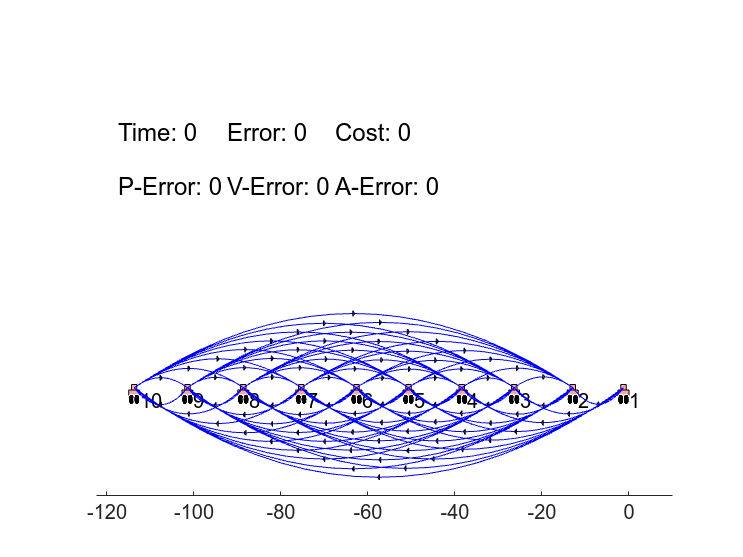

fig1 = figure;
ax1 = gca;                   % gca = get current axis handle
ax1.YAxis.Visible = 'off';   % hide out the y-axis from the plot
net0.drawNetwork(fig1)

Removing a vehicle and plotting the result

net1 = net0.copy();
net1.removeVehicles(1,[4,7],0); %errorDynamicsType argument left zero

disp(['Platoon after removing Vehicle 4 and Vehicle 7:'])

Platoon after removing Vehicle 4 and Vehicle 7:


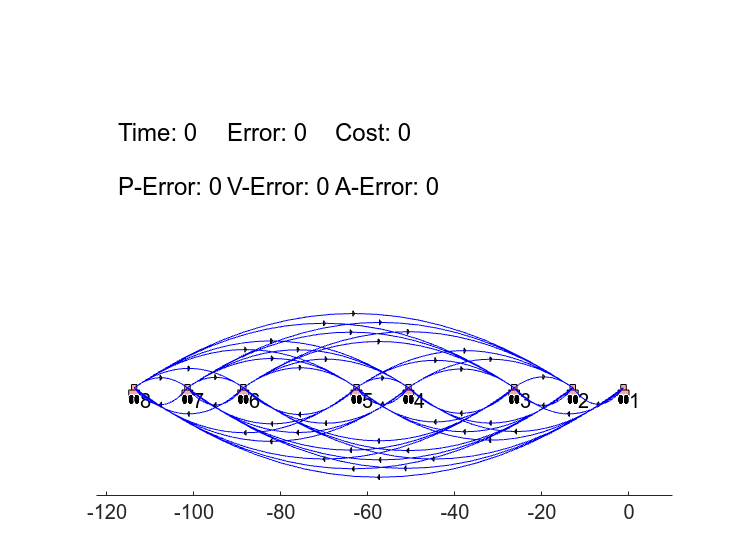

% Platoon simulation video figure setup
fig2 = figure;
ax2 = gca;                   % gca = get current axis handle
ax2.YAxis.Visible = 'off';   % hide out the y-axis from the plot
net1.drawNetwork(fig2)

#### Synthesizing controllers for the platoon

**Configuration 1:** Centralized Stabilizing Control using Error Dynamics II

Note: Local passivating controller synthesis should not use a cost function in order to get a set of local controller gain coefficients that are smaller (and thus, practical).

net1C = net1.copy();

errorDynamicsType = 2;  % Error dynamics formulation 1 or 2
isCentralized = 1;      % Centralized or decentralized controller synthesis
isDSS = 0;               % Involve DSS constraints (1) or not (0)
isOnlyStabilizing = 1;  % Stabilizing controller or Disturbance robust Controller)
gammaSqBar = 10;        % For the constraint: gamma^2 <= gammaSqBar % Desired max noise attenuation

%%% Parameterized approach to co-design
%% Optimizing gammaSq with respect to the co-design parameters
% pVals = net1.optimizeCodesignParameters(isCentralized,isDSS)

%% An alternative: Trying some fixed set of parameters.
pVals = 0.15*ones(numOfPlatoons,max(numOfVehicles));


%%% Local passivating controller synthesis specifications 
% LowerBound on \nu and upperBound on \rho 
nuBar = -40;       % For the constraint: nuBar <= nu       
rhoBar = 15;       % For the constraint: rhoHat <= rho <= rhoBar

tic
net1C.loadPlatoonControllers(errorDynamicsType,isCentralized,isDSS,isOnlyStabilizing,gammaSqBar,nuBar,rhoBar,pVals);

PVal =     1.0110   -0.6791   -0.1204
   -0.6791    0.5793   -0.8324
   -0.1204   -0.8324    6.9331


KVal =     1.1315   -2.1370  -24.8517


LVal = 1.0e+03 *

   -1.2590   -1.8324   -0.2454


nuVal = -1.5021

rhoVal = 0.7245

TestVal = -nu,rhoTilde/4


val =     1.5021    0.3451


Synthesis Success at Vehicle 2.


PVal =     1.0110   -0.6791   -0.1204
   -0.6791    0.5793   -0.8324
   -0.1204   -0.8324    6.9331


KVal =     1.1315   -2.1370  -24.8517


LVal = 1.0e+03 *

   -1.2590   -1.8324   -0.2454


nuVal = -1.5021

rhoVal = 0.7245

TestVal = -nu,rhoTilde/4


val =     1.5021    0.3451


Synthesis Success at Vehicle 3.


PVal =     1.0110   -0.6791   -0.1204
   -0.6791    0.5793   -0.8324
   -0.1204   -0.8324    6.9331


KVal =     1.1315   -2.1370  -24.8517


LVal = 1.0e+03 *

   -1.2590   -1.8324   -0.2454


nuVal = -1.5021

rhoVal = 0.7245

TestVal = -nu,rhoTilde/4


val =     1.5021    0.3451


Synthesis Success at Vehicle 4.


PVal =     1.0110   -0.6791   -0.1204
   -0.6791    0.5793   -0.8324
   -0.1204   -0.8324    6.9331


KVal =     1.1315   -2.1370  -24.8517


LVal = 1.0e+03 *

   -1.2590   -1.8324   -0.2454


nuVal = -1.5021

rhoVal = 0.7245

TestVal = -nu,rhoTilde/4


val =     1.5021    0.3451


Synthesis Success at Vehicle 5.


PVal =     1.0110   -0.6791   -0.1204
   -0.6791    0.5793   -0.8324
   -0.1204   -0.8324    6.9331


KVal =     1.1315   -2.1370  -24.8517


LVal = 1.0e+03 *

   -1.2590   -1.8324   -0.2454


nuVal = -1.5021

rhoVal = 0.7245

TestVal = -nu,rhoTilde/4


val =     1.5021    0.3451


Synthesis Success at Vehicle 6.


PVal =     1.0110   -0.6791   -0.1204
   -0.6791    0.5793   -0.8324
   -0.1204   -0.8324    6.9331


KVal =     1.1315   -2.1370  -24.8517


LVal = 1.0e+03 *

   -1.2590   -1.8324   -0.2454


nuVal = -1.5021

rhoVal = 0.7245

TestVal = -nu,rhoTilde/4


val =     1.5021    0.3451


Synthesis Success at Vehicle 7.


PVal =     1.0110   -0.6791   -0.1204
   -0.6791    0.5793   -0.8324
   -0.1204   -0.8324    6.9331


KVal =     1.1315   -2.1370  -24.8517


LVal = 1.0e+03 *

   -1.2590   -1.8324   -0.2454


nuVal = -1.5021

rhoVal = 0.7245

TestVal = -nu,rhoTilde/4


val =     1.5021    0.3451


Synthesis Success at Vehicle 8.


obj =   Platoon with properties:

     platoonIndex: 1
    numOfVehicles: 8
         vehicles: [1×8 Vehicle]
         topology: [1×1 Topology]
        graphics1: []
        graphics2: []
                K: {7×7 cell}
                R: []
        KSequence: []


Synthesis Success at Platoon 1.


toc

Elapsed time is 1.024216 seconds.



disp(['Platoon after synthesizing the topology:'])

Platoon after synthesizing the topology:


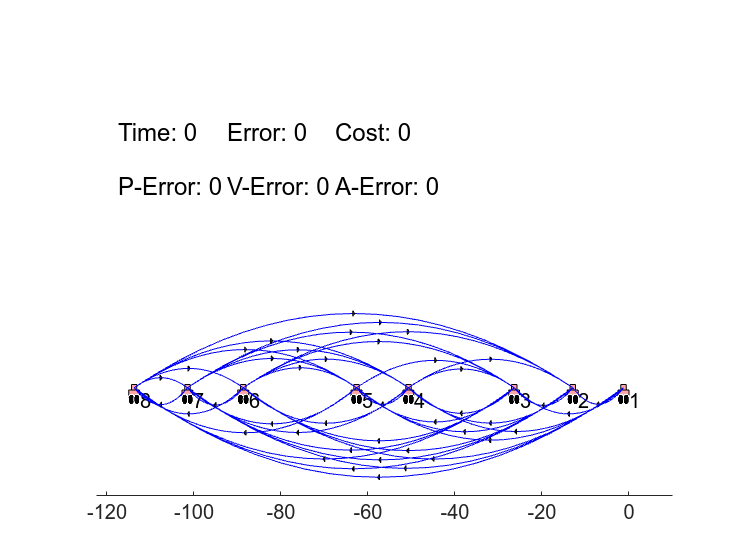

%%% Graphing the Resulting topology
fig3C = figure;
ax3 = gca;                   % gca = get current axis handle
ax3.YAxis.Visible = 'off';   % hide out the y-axis from the plot
net1C.drawNetwork(fig3C)

**Configuration 2:** Centralized Robust Control using Error Dynamics II

Note: In the local passivating controller synthesis, when no cost function is used, the resulting passivity indices are not amenable to global controller synthesis. 

To resolve this, we can resort to using the fundamental cost function for local passicating controller synthesis. However, this leads to: (Issue 1) larger local controller gains, and (Issue 2) global controller gains with no inter-vehicle interconnections. 

To solve the first issue, we can resort to use a cost function (in local passivating controller synthesis) of the form: 0.0000001*(- nu + rhoBar); This leads to relatively low local controller gains as well as passivity indices that are amenable to global controller synthesis. However, (Issue 2) is still a problem. 

net1D = net1.copy();

%%% Global controller synthesis specifications
% Error dynamics I/II, centralized/decentralized, stabilizing/robust, and upperBound on \gamma^2
errorDynamicsType = 2;  % Error dynamics formulation 1 or 2
isCentralized = 0;      % Centralized or decentralized controller synthesis
isDSS = 0;               % Involve DSS constraints (1) or not (0)
isOnlyStabilizing = 0;  % Stabilizing controller or Disturbance robust Controller)
gammaSqBar = 10;        % For the constraint: gamma^2 <= gammaSqBar % Desired max noise attenuation

%%% Parameterized approach to co-design
%% Optimizing gammaSq with respect to the co-design parameters
% pVals = net1.optimizeCodesignParameters(isCentralized,isDSS)

%% An alternative: Trying some fixed set of parameters.
pVals = 0.15*ones(numOfPlatoons,max(numOfVehicles));


%%% Local passivating controller synthesis specifications 
% LowerBound on \nu and upperBound on \rho 
nuBar = -40;       % For the constraint: nuBar <= nu       
rhoBar = 15;       % For the constraint: rhoHat <= rho <= rhoBar

tic
net1D.loadPlatoonControllers(errorDynamicsType,isCentralized,isDSS,isOnlyStabilizing,gammaSqBar,nuBar,rhoBar,pVals);

Robust Stabilizing at: 1 after .
Local Synthesis Success at: 1 with gammaSq=2.9519.
Data saved at: 1.
LMI is feasible at: 1, thus continued.
Decentralized Synthesis Success at: 1 with gammaSq=3.0366.
Elapsed time is 0.280767 seconds.
Current K at i = 1
   -0.0000    0.0000   -0.0000
    0.0000   -0.0000   -0.0000
    0.0000   -0.0000   -0.0254

Robust Stabilizing at: 2 after 1.
Local Synthesis Success at: 2 with gammaSq=2.9519.
Data saved at: 2 after 1.
LMI is feasible at: 2 after 1.
Decentralized Synthesis Success at: 2 with gammaSq=3.0366.
Elapsed time is 0.237689 seconds.
 Local controller updated at j = 1
Current K at i = 2
   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.0000   -0.0000   -0.0254   -0.0000   -0.0000    0.0002
    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.025

obj =   Platoon with properties:

     platoonIndex: 1
    numOfVehicles: 8
         vehicles: [1×8 Vehicle]
         topology: [1×1 Topology]
        graphics1: []
        graphics2: []
                K: {7×7 cell}
                R: []
        KSequence: {{1×1 cell}  {2×2 cell}  {3×3 cell}  {4×4 cell}  {5×5 cell}  {6×6 cell}  {7×7 cell}}


Synthesis Success at Platoon 1.


toc

Elapsed time is 0.265664 seconds.



disp(['Platoon after synthesizing the topology:'])

Platoon after synthesizing the topology:


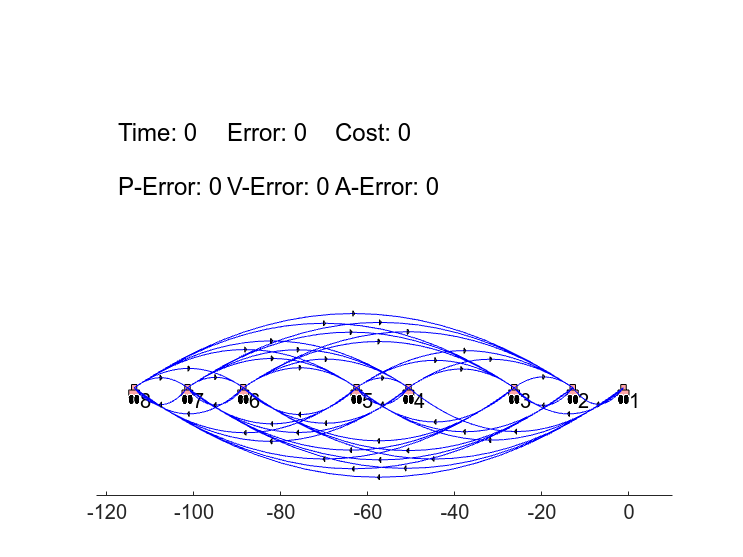

%%% Graphing the Resulting topology
fig3D = figure;
ax3 = gca;                   % gca = get current axis handle
ax3.YAxis.Visible = 'off';   % hide out the y-axis from the plot
net1D.drawNetwork(fig3D)



%%% To check compositionality, lets see K_{13} value at decentralized iteration = 3,4,5 and 6
% format long
net1D.platoons(1).KSequence

ans = 1×7 cell array
    {1×1 cell}    {2×2 cell}    {3×3 cell}    {4×4 cell}    {5×5 cell}    {6×6 cell}    {7×7 cell}


ans = 1.0e-03 *

   -0.0000   -0.0000   -0.0000
   -0.0000   -0.0000   -0.0000
   -0.0000   -0.0000    0.1795


ans = 1.0e-03 *

   -0.0000   -0.0000   -0.0000
   -0.0000   -0.0000   -0.0000
   -0.0000   -0.0000    0.1795


Platoon with only 2 vehicles:


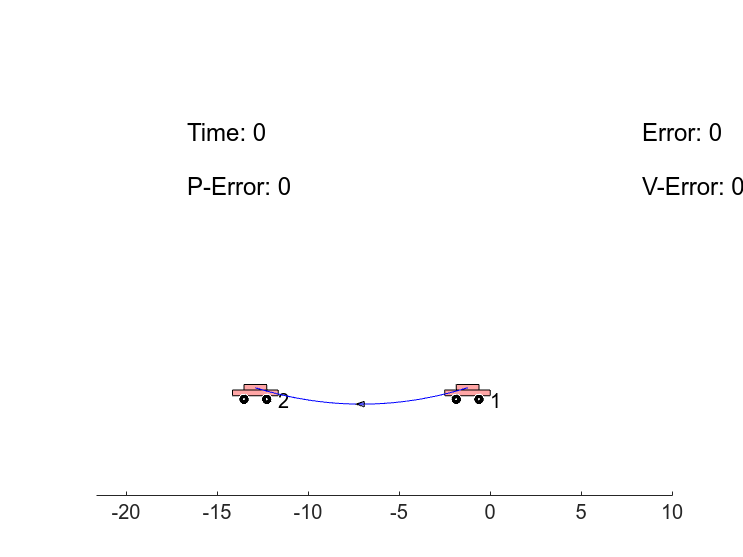

Platoon with only 3 vehicles:


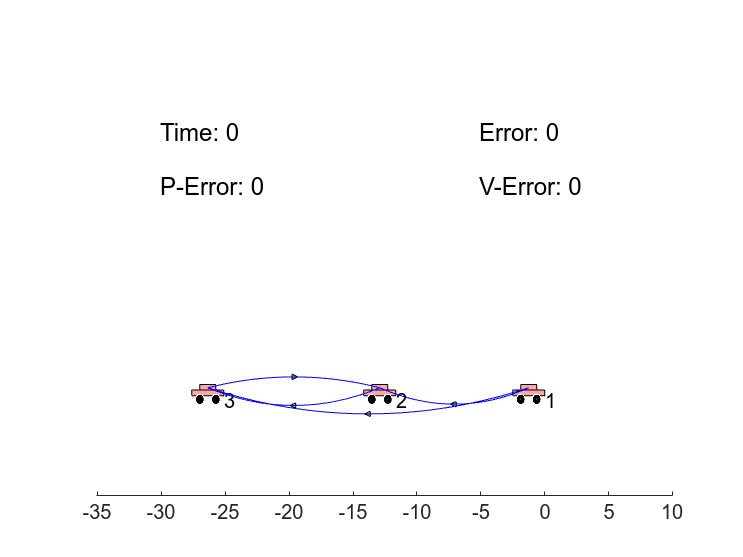

Platoon with only 4 vehicles:


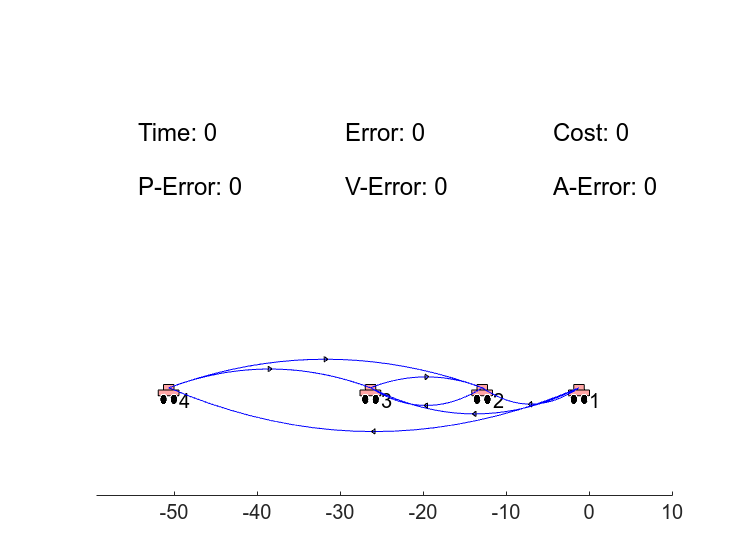

Platoon with only 5 vehicles:


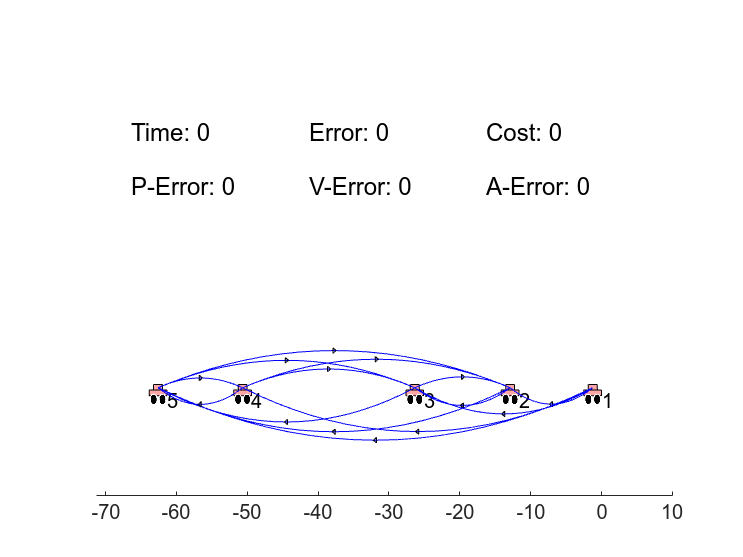

Platoon with only 6 vehicles:


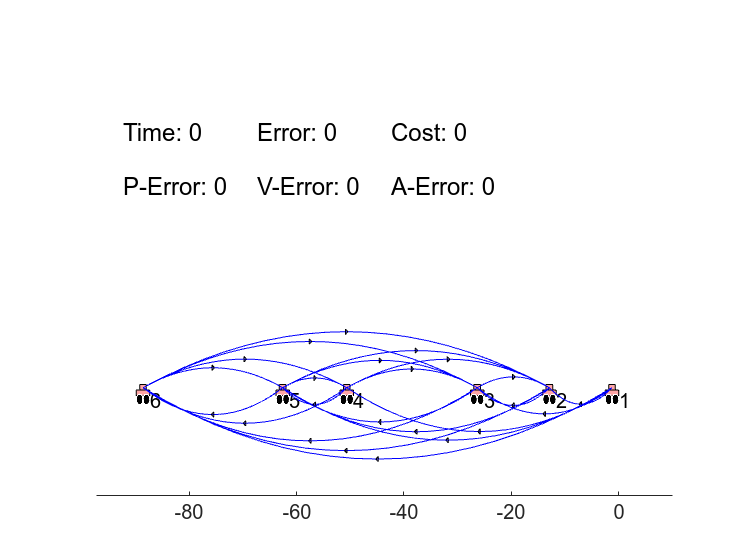

Platoon with only 7 vehicles:


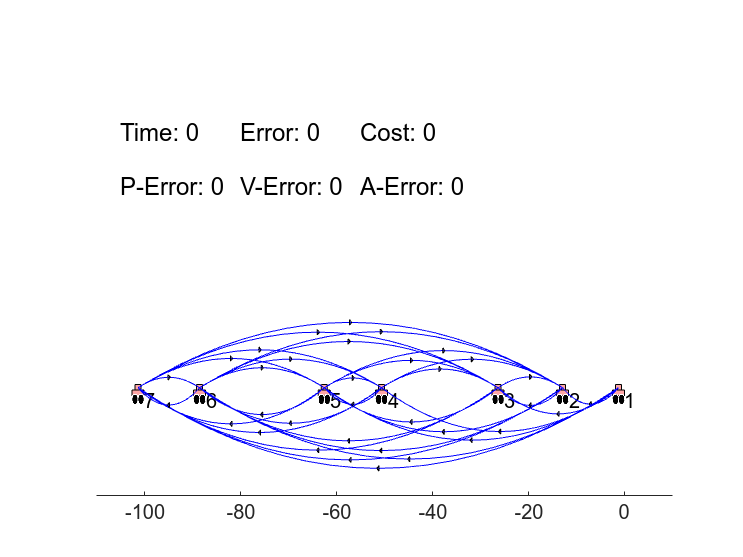

Platoon with only 8 vehicles:


if ~isCentralized
    net1D.platoons(1).KSequence{3}{1,3}
    net1D.platoons(1).KSequence{4}{1,3}
    % net1.platoons(1).KSequence{5}{1,3}
    % net1.platoons(1).KSequence{6}{1,3}

    %%% Plotting intermediate topologies
    N = net1D.platoons(1).numOfVehicles;
    for i = 1:N-1
        net1_i = net1D.copy();
        net1_i.removeVehicles(1,[(i+2):N],errorDynamicsType);
        disp(['Platoon with only ',num2str(i+1),' vehicles:'])
        fig4{i} = figure; 
        ax4{i} = gca;                   % gca = get current axis handle
        ax4{i}.YAxis.Visible = 'off';   % hide out the y-axis from the plot
        net1_i.drawNetwork(fig4{i})
        net1_i = net1_i.copy();
    end
end






%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Compute the cost \sum_{i=1}^N cij*|K_ij|+c0*gamma

%Then we use hard constraint

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%%% In decentralized implementation, there are two things to consider:
% gammaSq_i needs to be costrainted at each subsystem i (or penalized considerably), 
% otherwise it tends to grow with i. Recall that max(gammaSq_i) = gammaSq. 
% There is a zero eigenvalue in the main LMI constraint (this is also in the
% centralized problem). This may be the reason why solver gives "Unknown Status" error.


%%% To further check compositionality, lets remove a vehicle
net2 = net1D.copy();
net2.removeVehicles(1,[5],errorDynamicsType);

disp(['Platoon after removing Vehicle 5:'])

Platoon after removing Vehicle 5:


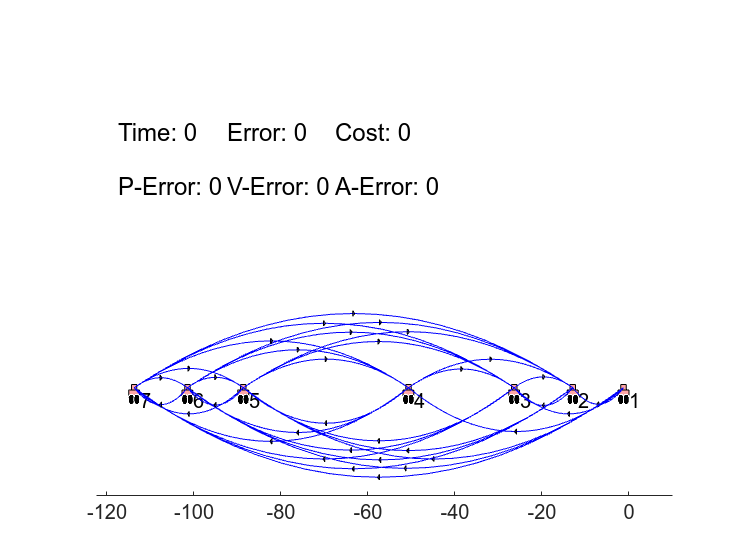

% Platoon simulation video figure setup
fig5 = figure; 
ax5 = gca;                   % gca = get current axis handle
ax5.YAxis.Visible = 'off';   % hide out the y-axis from the plot
net2.drawNetwork(fig5)

Avoid controller gain filtering by including a threshold in the local LMI problems

optimizing pvals

Running the Simulation - Updating the states

disp(['Platoon Simulation:'])

Platoon Simulation:


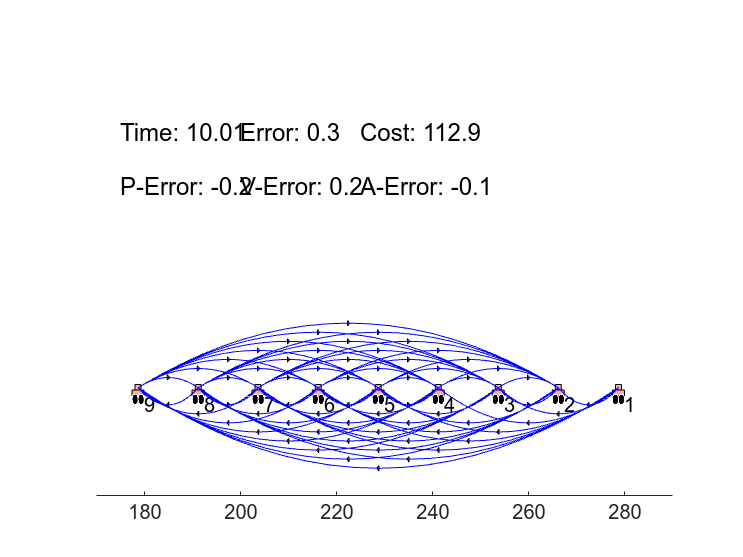

net = net2.copy();
% Platoon simulation video figure setup
fig5 = figure;
ax5 = gca;                   % gca = get current axis handle
ax5.YAxis.Visible = 'off';   % hide out the y-axis from the plot
net.drawNetwork(fig5)


% Update the states and plot them in real time as an animation
dt = 0.01;
tMax = 10; 
tArray = 0:dt:tMax;
timeLength = length(tArray);

% Leader's trajectory specification
tVals = tMax*[0,0.2,0.4,0.6,0.8,1];     % Special time instants (inbetween which the acceleration is constant)
vVals = [0,30,40,40,20,20];  % Velocities to be achived at these time instants
net.generateLeadersControlProfiles(dt,tVals,vVals);

% Updating the platoons
for t = tArray

    % Use this update function to achieve the update of the entire program
    net.update(t,dt);
    net.redrawNetwork(fig5)
    pause(0.01)

end

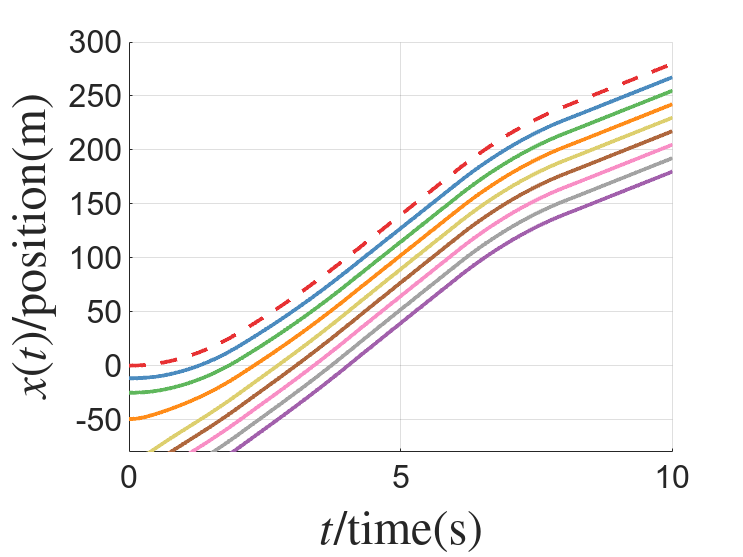



% Plot the state histories
C = linspecer(net.platoons(1).numOfVehicles(1));


figure
axes('NextPlot','replacechildren', 'ColorOrder',C);
hold on
plot(tArray,net.platoons(k).vehicles(1).stateHistory(1,:)','--',LineWidth=2);
for k = 1:1:net.numOfPlatoons
    for i = 2:1:net.platoons(k).numOfVehicles
        plot(tArray,net.platoons(k).vehicles(i).stateHistory(1,:)','-',LineWidth=2);
    end
end
set(gca,fontsize=16);
xlabel('$t$/time(s)','Interpreter','latex',fontsize=24)
ylabel('$x(t)$/position(m)','Interpreter','latex',fontsize=24)
% legend(Location="eastoutside")
xlim([0 10]);
ylim([-80 300]);
grid on 

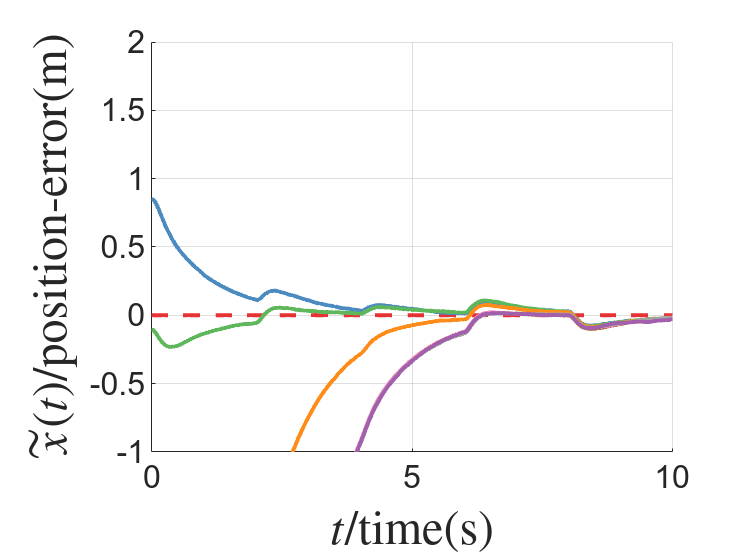



% Plot the location error histories
figure
axes('NextPlot','replacechildren', 'ColorOrder',C);
hold on
plot(tArray,zeros(1,timeLength),'--',LineWidth=2);
for k = 1:1:net.numOfPlatoons
    for i = 2:1:net.platoons(k).numOfVehicles
        plot(tArray,net.platoons(k).vehicles(i).errorHistory(1,:)','-',LineWidth=2);
    end
end
set(gca,fontsize=16);
xlabel('$t$/time(s)','Interpreter','latex',fontsize=24)
ylabel('$\tilde{x}(t)$/position-error(m)','Interpreter','latex',fontsize=24)
% legend(Location="eastoutside")
xlim([0 10]);
ylim([-1 2]);
grid on 

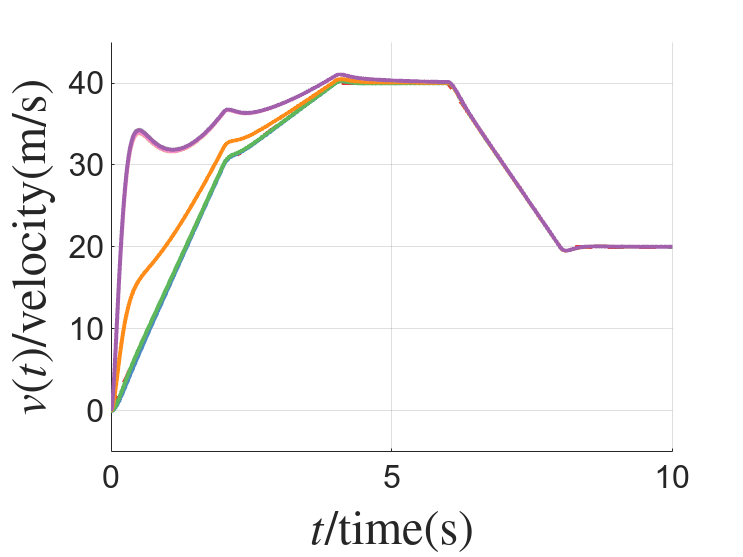



figure
axes('NextPlot','replacechildren', 'ColorOrder',C);
hold on
plot(tArray,net.platoons(k).vehicles(1).stateHistory(2,:)','--',LineWidth=2);
for k = 1:1:net.numOfPlatoons
    for i = 2:1:net.platoons(k).numOfVehicles
        plot(tArray,net.platoons(k).vehicles(i).stateHistory(2,:)','-',LineWidth=2);
    end
end
set(gca,fontsize=16);
xlabel('$t$/time(s)','Interpreter','latex',fontsize=24)
ylabel('$v(t)$/velocity(m/s)','Interpreter','latex',fontsize=24)
% legend(Location="eastoutside")
xlim([0 10]);
ylim([-5 45]);
grid on 

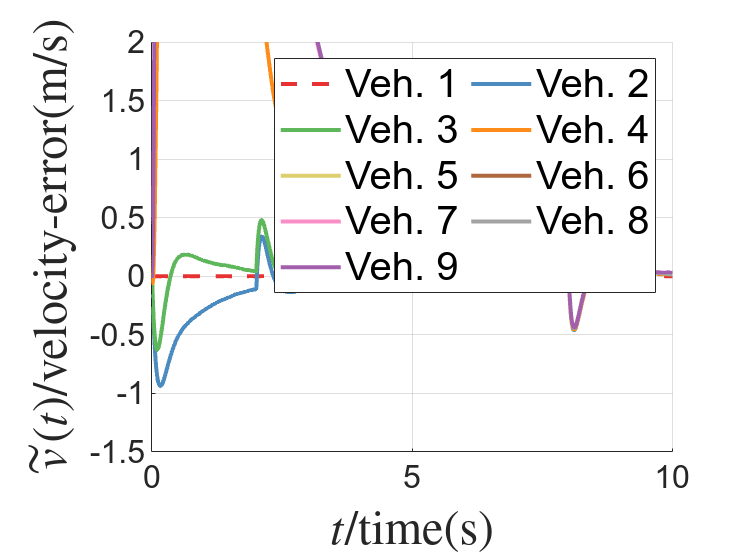




figure
axes('NextPlot','replacechildren', 'ColorOrder',C);
hold on
plot(tArray,zeros(1,timeLength),'--',LineWidth=2,DisplayName=['Veh. ',num2str(1)]);
for k = 1:1:net.numOfPlatoons
    for i = 2:1:net.platoons(k).numOfVehicles
        plot(tArray,net.platoons(k).vehicles(i).errorHistory(2,:)','-',LineWidth=2,DisplayName=['Veh. ',num2str(i)]);
    end
end
set(gca,fontsize=16);
xlabel('$t$/time(s)','Interpreter','latex',fontsize=24)
ylabel('$\tilde{v}(t)$/velocity-error(m/s)','Interpreter','latex',fontsize=24)
legend(Location="northeast",FontSize=20,NumColumns=2,Orientation="horizontal")
xlim([0 10]);
ylim([-1.5 2]);
grid on 

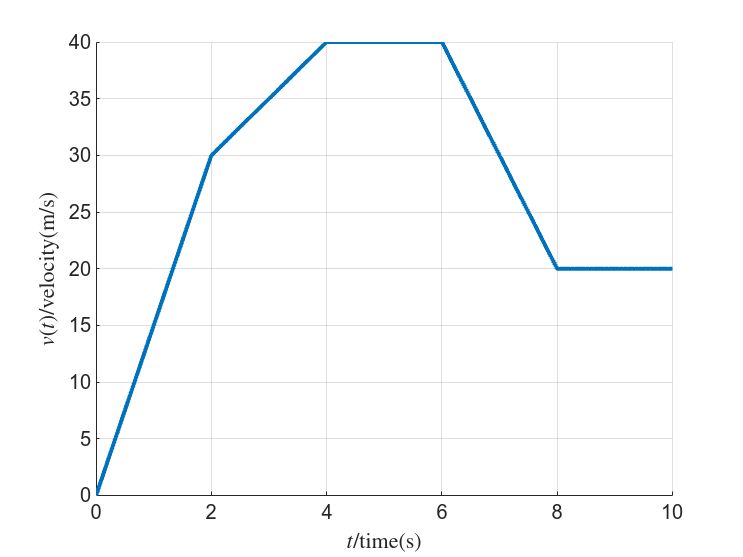



% % Plot the state histories of leaders
% figure
% hold on
% for k = 1:1:net.numOfPlatoons
%     for i = 1
%         plot(tArray,net.platoons(k).vehicles(i).stateHistory(1,:)','-',LineWidth=2,DisplayName=['Veh. ',num2str(i)]);
%     end
% end
% xlabel('$t$/time(s)','Interpreter','latex')
% ylabel('$x(t)$/position(m)','Interpreter','latex')
% % legend(Location="eastoutside")
% grid on 
% 
% 
figure
hold on
for k = 1:1:net.numOfPlatoons
    for i = 1
        plot(tArray,net.platoons(k).vehicles(i).stateHistory(2,:)','-',LineWidth=2,DisplayName=['Veh. ',num2str(i)]);
    end
end
xlabel('$t$/time(s)','Interpreter','latex')
ylabel('$v(t)$/velocity(m/s)','Interpreter','latex')
% legend(Location="eastoutside")
grid on 

Ideas to pursue next:

What is the best set of passivity information for this topology synthesis?

Leader's connection design (Centralized Setting, ED-I)

For the case with z = C e

Local controller design for passivation